clear all
close all
clc

% mechanic transmittion
mech.L   = 0.2;
mech.l   = 0.055;
mech.hp  = 0.083;
mech.H   = 0.18;
mech.Hp  = 0.012;
mech.hf  = 0.24;
mech.hfp = 0.035;

assert(mech.hp+mech.H+mech.Hp==mech.hf+mech.hfp)

% physics constants
const.g       = 9.80665;
const.rad2deg = 180/pi;
const.deg2rad = 1/const.rad2deg;
ozin2Nm       = 0.706e-2;

% H-bridge L293D motor drive
driver.kc = 1;
driver.Tc = 2e-9;

% Longruner Nema 17 17HS13-0404S stepper motor
stepper.La = 37e-3;
stepper.Ra = 30;
stepper.Vn = 12;
stepper.In = 0.4;
% holding torque is 36.8 oz.in.
stepper.tau_hold = 36.8 * ozin2Nm;
stepper.Km = stepper.tau_hold / stepper.In;
stepper.tausf = 0;
% rotor's diameter is 5 mm
stepper.rotor_r = 2.5e-3;
% rotor's inertia is 35 g cm^2
stepper.I = 35 * 1e-3 * 1e-2 * 1e-2; % Kg m^2
stepper.Jm = stepper.I / const.g;
stepper.Bm = 2.5e-7;
stepper.Nr = 100;
stepper.p = 2;
stepper.pp = stepper.Nr/stepper.p;
stepper.precision = 360/(stepper.p*stepper.Nr);
stepper.precision2 = stepper.precision/2;

stepper.Tstep = 2e-3;
stepper.Tstep2 = 1e-3;

stepper.Jeq = stepper.Jm;
stepper.Beq = stepper.Bm;

beam.m = 0.130;

% arduino
arduino.arch = 8;
arduino.vcc = 5;
arduino.gnd = 0;
arduino.adc.n_bits = 10;
arduino.adc.q_step = (arduino.vcc - arduino.gnd)/(2^(arduino.adc.n_bits));
arduino.adc.fc = 9615;

% VL53L0X time-of-flight laser distance sensor
sensor.distance.precision = 1e-3;
sensor.distance.Ts        = 10e-3;
ballnbeam.controller.Tc   = 20e-3;

% ball
ball.m = 0.0027;
ball.r = 0.02;
ball.I = 2/3*ball.m*ball.r*ball.r;

request.Mp = 0.1;
request.ts = 3;

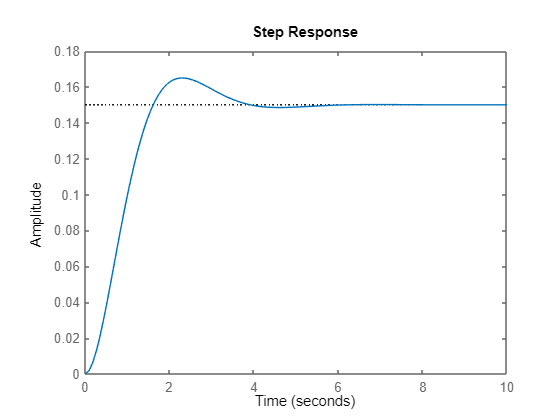

b2 = (ball.m*const.g)/(ball.I/(ball.r^2)+ball.m)*(mech.l/mech.L);
ballnbeam.A = [0 1; 0 0];
ballnbeam.b = [0; b2];
ballnbeam.C = [1 0];
ballnbeam.d = 0;
delta = log(1/request.Mp)/sqrt(pi^2 + log(1/request.Mp)^2);
wn    = 3/(delta*request.ts);

p1    = -delta*wn + 1i*wn*sqrt(1-delta^2);
p2    = conj(p1);
ballnbeam.controller.K = -place(ballnbeam.A, ballnbeam.b, [p1 p2]);

sys = ss(ballnbeam.A, ballnbeam.b, ballnbeam.C, ballnbeam.d);

gains = [ballnbeam.A ballnbeam.b; ballnbeam.C ballnbeam.d]\[0;0;1];

ballnbeam.controller.Nx = [gains(1,1);gains(2,1)];
ballnbeam.controller.Nu = gains(3,1);
ballnbeam.controller.Nbar = -(ballnbeam.controller.Nu+ballnbeam.controller.K*ballnbeam.controller.Nx);
stable_sys = ss(ballnbeam.A+ballnbeam.b*ballnbeam.controller.K,ballnbeam.b,ballnbeam.C,ballnbeam.d);
step(0.15*ballnbeam.controller.Nbar*stable_sys,10)

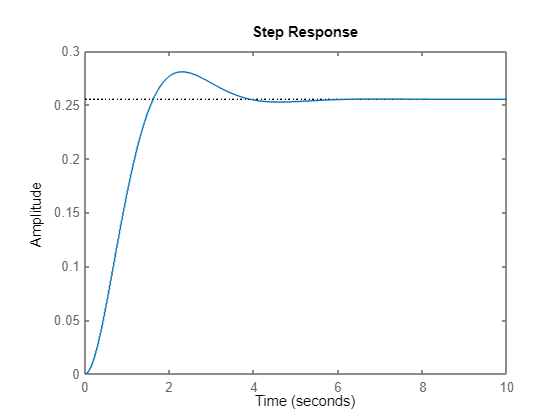

%% Digital
sysd = c2d(sys, ballnbeam.controller.Tc, 'tustin');
ballnbeam.Ad = sysd.A;
ballnbeam.bd = sysd.B;
ballnbeam.Cd = sysd.C;
ballnbeam.dd = sysd.D;
gains = [ballnbeam.Ad ballnbeam.bd; ballnbeam.Cd ballnbeam.dd]\[0;0;1];

ballnbeam.controller.Nxd = [gains(1,1);gains(2,1)];
ballnbeam.controller.Nud = gains(3,1);

p1d = exp(p1*ballnbeam.controller.Tc);
p2d = exp(p2*ballnbeam.controller.Tc);
ballnbeam.controller.Kd = -place(ballnbeam.Ad, ballnbeam.bd, [p1d p2d]);
ballnbeam.controller.Nbard = -(ballnbeam.controller.Nud+ballnbeam.controller.Kd*ballnbeam.controller.Nxd);
stable_sysd = ss(ballnbeam.Ad+ballnbeam.bd*ballnbeam.controller.Kd,ballnbeam.bd,ballnbeam.Cd,ballnbeam.dd, ballnbeam.controller.Tc);
step(0.25*ballnbeam.controller.Nbar*stable_sysd,10)

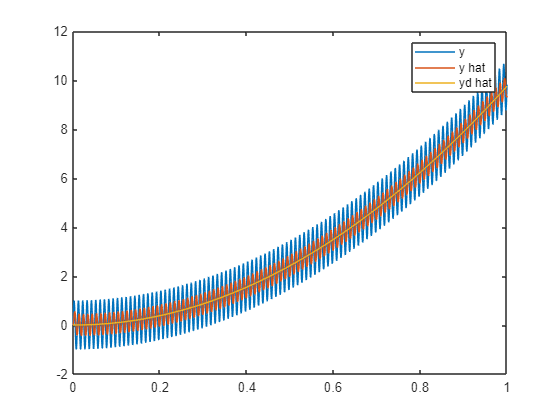

Hd =
 
  3.142 z + 3.142
  ---------------
  5.142 z + 1.142
 
Sample time: 0.01 seconds
Discrete-time transfer function.



%% Filter
% actual signal (ball position)
alpha = 9.81;
t = 0:0.00001:1;
u = zeros(1,size(t,2));

for j = 1:size(u,2)
    u(1,j) = alpha * t(1,j)^2;
end

% noise
fc_noise = 1/sensor.distance.Ts;
e0 = sin(2*pi*fc_noise*t);

% data creation
y = u + e0;

% digital acquisition data
td = 0:sensor.distance.Ts:1;
ud = zeros(1,size(td,2));

for j = 1:size(ud,2)
    ud(1,j) = alpha * td(1,j)^2;
end

% noise
e0d = sin(2*pi*fc_noise*td);

% data creation
yd = ud + e0d;

% filtering
mu0 = 2*pi/ballnbeam.controller.Tc;
s = tf('s');
H = mu0 / ( s + mu0 );
y_hat = lsim(H, y, t);

z = tf('z', sensor.distance.Ts);
Hd = mu0 * sensor.distance.Ts * (z + 1) / (z * (2 + mu0 * sensor.distance.Ts) + (-2 + mu0 * sensor.distance.Ts));
yd_hat = lsim(Hd, yd, td);

plot(t, y)
hold on
plot(t, y_hat)
plot(td, yd_hat)
legend("y","y hat","yd hat")

[ballnbeam.filter.num, ballnbeam.filter.den] = tfdata(Hd);
ballnbeam.filter.num = cell2mat(ballnbeam.filter.num);
ballnbeam.filter.den = cell2mat(ballnbeam.filter.den);
tmp = ballnbeam.filter.den(1);
ballnbeam.filter.a0 = ballnbeam.filter.den(1)/tmp;
ballnbeam.filter.a1 = -ballnbeam.filter.den(2)/tmp;
ballnbeam.filter.b0 = ballnbeam.filter.num(1)/tmp;
ballnbeam.filter.b1 = ballnbeam.filter.num(2)/tmp;

%% Integral Action
ballnbeam.Ae = [0 ballnbeam.C;[0;0] ballnbeam.A];
ballnbeam.Be = [0;ballnbeam.b];

sigma = -delta*wn;
wd = wn*sqrt(1-delta^2);

poles = [2*sigma + 1i*wd, 2*sigma - 1i*wd, 2*sigma];

Ke = -place(ballnbeam.Ae,ballnbeam.Be,poles);
ballnbeam.controller.Ki = Ke(1);
ballnbeam.controller.Ke = Ke(1,2:3);